# **pJacobiOmega**

Legendre form of jacobian omega function

## Definition


$$\Omega \left(\phi ,\nu \left|m\right.\right)\equiv \Pi \left(\phi ,\nu \left|m\right.\right)-\frac{\Pi \left(\nu \left|m\right.\right)}{K\left(m\right)}F\left(\phi |m\right)$$



$$\Omega \left(\phi ,\nu ,k\right)\equiv \Omega \left(\phi ,\nu \left|k^2 \right.\right)$$


where $\phi$ is the argument, $\nu$ is the characteristic, *k *is the modulus,  *m *is the parameter ,  $K\left(m\right)$ is the complete elliptic integral of the first kind, $\Pi \left(\nu \left|m\right.\right)$ is the  the complete elliptic integral of the third kind, and $F\left(\phi |m\right)$ and $\Pi \left(x,\nu \left|m\right.\right)$ are the Legendre elliptic integral of the first and  third kind.

**Note. **Notation $\Omega \left(\phi ,\nu \left|m\right.\right)$ and the name pJacobiOmega are **not** standard. $\Omega \left(\phi ,\nu \left|m\right.\right)$ is **not **periodic part of $\Pi \left(\phi ,\nu \left|m\right.\right)$.

Domain:   If $-\infty <m\le 1$(or $\left.|k|\le 1\right)$ and and $-\infty <\nu <1$ then $-\infty \le \phi \le \infty$ . For the specified domain, the  codomain is the set of real numbers.

Basic features:

$\Omega \left(-\phi ,\nu \left|m\right.\right)=-\Omega \left(\phi ,\nu \left|m\right.\right)$   (odd)

 $\Omega \left(n\;\pi \pm x,\nu \left|m\right.\right)=\Omega \left(x,\nu \left|m\right.\right),\;\;\;\left|\phi \right|\le \pi /2$  (periodic)

Special values:

$\Omega \left(0,\nu \left|m\right.\right)$,    $\Omega \left(x,0\left|m\right.\right)=0$,    $\Omega \left(x,0\left|0\right.\right)=0$,    $\Omega \left(x,1\left|0\right.\right)=-\infty$ 

Identities:

## Syntax

Y = pJacobiOmega(PHI,NU,K)

y = pjomega(phi,nu,k)

Y = mpJacobiOmega(PHI,NU,M)

y = mpjomega(phi,nu,m)

## Description

**Y = pJacobiOmega(PHI,NU,K)** returns $\Omega \left(\phi ,\nu ,k\right)$ for each element of the arrays PHI , NU (the characteristic) and K (the modulus). PHI, NU and K must be real and the same size or any of them can be scalar. **pJacobiOmega** is the wrapper function which calls the functions **pjomega** element-wise via the function **ufun3**.

**y = pjomega(phi,k) **returns $\Omega \left(\phi ,\nu ,k\right)$ for the argument phi, the characteristic nu and the modulus k. It is assumed that  the input arguments are real **scalars** without check. y is NaN if any of   the input arguments is invalid or convergence failed. **pjomega** is the wrapper function which calls the functions **mpjomega**.

**Y = mpJacobiOmega(PHI,NU,M)** returns  $\Omega \left(\phi ,\nu \left|m\right.\right)$  for each element of the arrays PHI (the argument), NU (the characteristic) and M (the parameter). PHI, NU and M must be real and the same size or any of them can be scalar. **mpJacobiOmega** is the wrapper function which calls the functions **mpjomega** element-wise via the function **ufun3**.

**y = mpjomega(phi,nu,m)** returns $\Omega \left(\phi ,\nu \left|m\right.\right)$for  argument phi, the characteristic nu and the parameter m. It is assumed that the input arguments are real scalars without check. y is NaN if any of  the input arguments is invalid or convergence failed.  **mpjomega **call the  functions **mpelPi**, **mcelPi** and **melK **for calculation of $\Omega \left(\phi ,\nu \left|m\right.\right)$ .

## Precision

## **Numerical Examples**

**Scalar input**

format long
k = 0.5;
nu = 0.5;
phi = 1;
[pjomega(phi,nu,k), pJacobiOmega(phi,nu,k), mpjomega(phi,nu,k^2), mpJacobiOmega(phi,nu,k^2)]

ans =   -0.257280783403800  -0.257280783403800  -0.257280783403800  -0.257280783403800


Accuracy. 


fprintf('%.16g\n',pjomega(pi/4,1/2,1/2)) 

-0.2586324047753588


%Maple -0.2586324047753590_42

Special values

m = -0.5;
nu = 0.5;
phi = 10;
mpJacobiOmega(-phi,nu,m) + mpJacobiOmega(phi,nu,m)

ans = 0

mpJacobiOmega(0,nu,m)

ans = 0

disp(mpJacobiOmega(0,nu,m)-mpJacobiOmega(pi,nu,m))

     0



**Vector input**

nu = [0.1, 0.2, 0.3];
m = [-1, -2,-3];
disp(mpJacobiOmega(0,nu,m)-mpJacobiOmega(pi,nu,m))

     0     0     0



**Matrix input**

nu = [0.1, 0.2; 0.3 0.5];
m = [-1, -2;-3, -5];
disp(mpJacobiOmega(0,nu,m)-mpJacobiOmega(pi,nu,m))

     0     0
     0     0



## **Graphs **

**Example 1**

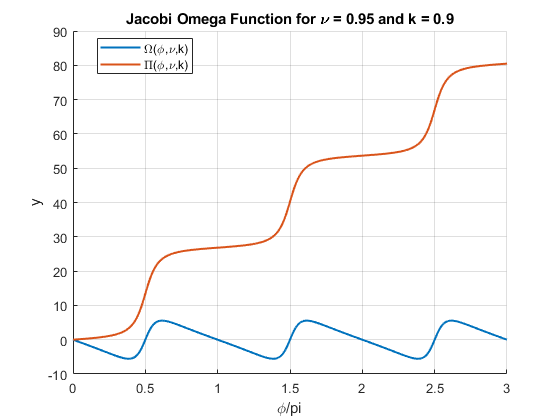

figure
hold on
phi=0:0.01:3;
nu = 0.95;
k = 0.9;
s = pi;
plot(phi,pJacobiOmega(s*phi,nu,k),'LineWidth',1.5)
plot(phi,pEllipticPi(s*phi,nu,k),'LineWidth',1.5)
xlabel('\phi/pi')
ylabel('y')
legend('\Omega(\phi,\nu,k)','\Pi(\phi,\nu,k)','Location','best')
%ylim([-1,4])
title(sprintf('Jacobi Omega Function for %s = %g and k = %g','\nu',nu,k))
grid on

**Example 2**

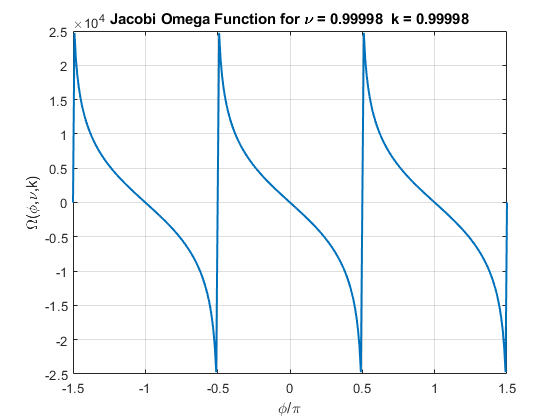

figure
phi=-1.5:0.01:1.5;
nu = 0.99998;
k = nu;
plot(phi,pJacobiOmega(pi*phi,nu,k),'LineWidth',1.5)
xlabel('\phi/\pi')
ylabel('\Omega(\phi,\nu,k)')
%xlim([-1.1 1.1])
%ylim([-2.2 2.2])
title(sprintf('Jacobi Omega Function for %s = %g  k = %g','\nu',nu,k))
grid on

**Example 3**

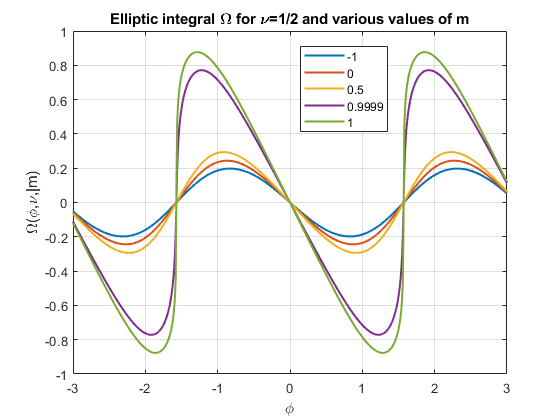

figure
PHI = -3:0.01:3;
nu = 0.5;
M = [-1,0,0.5,0.9999,0.999999];
SN = zeros(length(M),length(PHI));
clg{length(M)}=[];
for i = 1:length(M)
     clg{i} = num2str(M(i));
    SN(i,:) = mpJacobiOmega(PHI,nu,M(i));
end
plot(PHI,SN,'LineWidth',1.5)
%axis([min(PHI) max(PHI) -3 3])
grid on
legend(clg{1:length(M)},'Location','Best')
title('Elliptic integral \Omega for \nu=1/2 and various values of m')
xlabel('\phi')
ylabel('\Omega(\phi,\nu,|m)')

**Example 4**

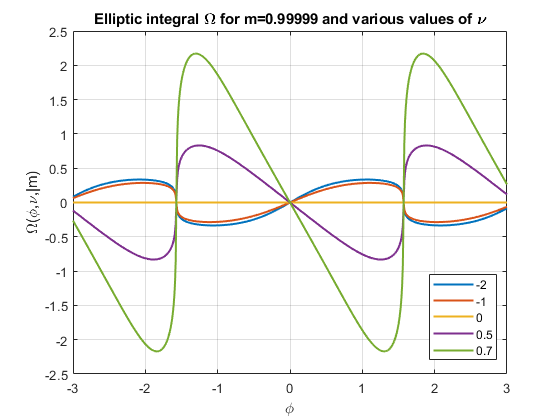

figure
PHI = -3:0.01:3;
NU = [-2,-1,0,0.5,0.7];
m = 0.99999;
SN = zeros(length(NU),length(PHI));
clg{length(NU)}=[];
for i = 1:length(NU)
     clg{i} = num2str(NU(i));
    SN(i,:) = mpJacobiOmega(PHI,NU(i),m);
end
plot(PHI,SN,'LineWidth',1.5)
%axis([min(PHI) max(PHI) -3 3])
grid on
legend(clg{1:length(NU)},'Location','Best')
title(sprintf('Elliptic integral %s for m=%g and various values of %s','\Omega',m,'\nu'))
xlabel('\phi')
ylabel('\Omega(\phi,\nu,|m)')

**Example 5**

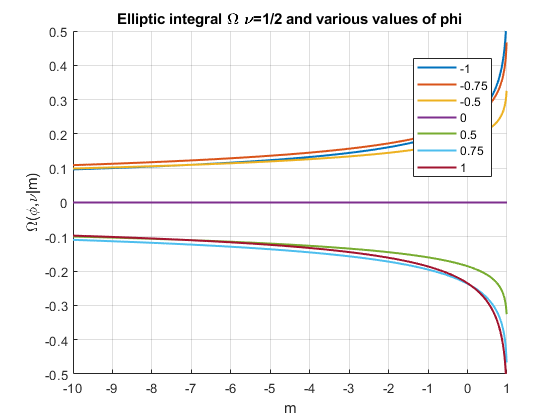

figure
hold on
nu = 0.5;
M = -10:0.01:1;
PHI = [-1,-0.75,-0.5,0,0.5,0.75,1];
SN = zeros(length(PHI),length(M));
clg{length(PHI)}=[];
for i = 1:length(PHI)
     clg{i} = num2str(PHI(i));
    SN(i,:) = mpJacobiOmega(PHI(i),nu,M);
end
plot(M,SN,'LineWidth',1.5)
axis([min(M) max(M) -0.5 0.5])
grid on
legend(clg{1:length(PHI)},'Location','Best')
title('Elliptic integral \Omega \nu=1/2 and various values of phi')
xlabel('m')
ylabel('\Omega(\phi,\nu|m)')
hold off

**Example 6**

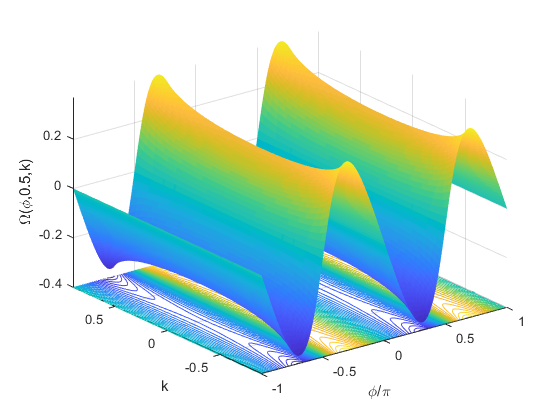

figure
phi=-1:0.01:1;
k=-0.9:0.01:0.9;
nu = 0.5;
[PHI,K]=meshgrid(phi,k);
hs=surfc(PHI,K,pJacobiOmega(PHI*pi,nu,K),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -0.4;
hc.LineWidth = 0.5;
hc.LevelList = -0.4:0.02:0.4;
caxis([-0.4 0.4])
view(3);
xlabel('\phi/\pi')
ylabel('k')
zlabel(sprintf('%s%g%s','\Omega(\phi,',nu,',k)'))
%zlim([-1 1])
grid on

**Example 7**

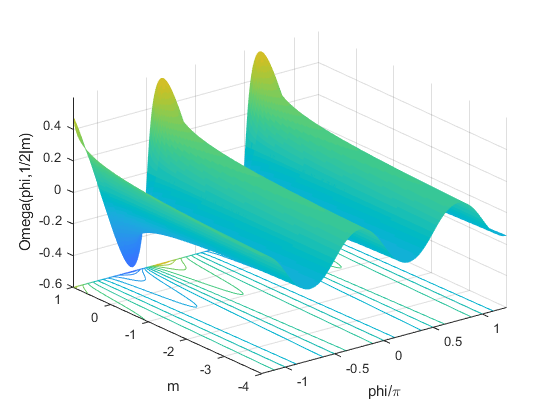

figure
phi=-1.25:0.01:1.25;
m=-4:0.01:1;
nu = 1/2;
[PHI,M]=meshgrid(phi,m);
hs=surfc(PHI,M,mpJacobiOmega(PHI*pi,nu,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -0.6;
hc.LineWidth = 0.5;
hc.LevelList = -0.6:0.1:0.6;
view(3)
caxis([-1 1])
xlabel('phi/\pi')
ylabel('m')
zlabel('Omega(phi,1/2|m)')
zlim([-0.6 0.6])
grid on

**Example 8**

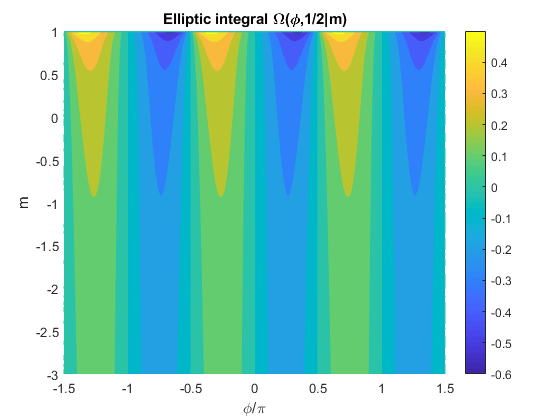

figure
nu = 0.5;
f = @(phi,m)mpJacobiOmega(phi*pi,nu,m);
fcontour(f,[-1.5 1.5 -3 1],'Fill','on','LevelList',-0.6:0.1:0.6,'MeshDensity',200)
title('Elliptic integral \Omega(\phi,1/2|m)')
colorbar
xlabel('\phi/\pi')
ylabel('m')
grid on

**Example 9**

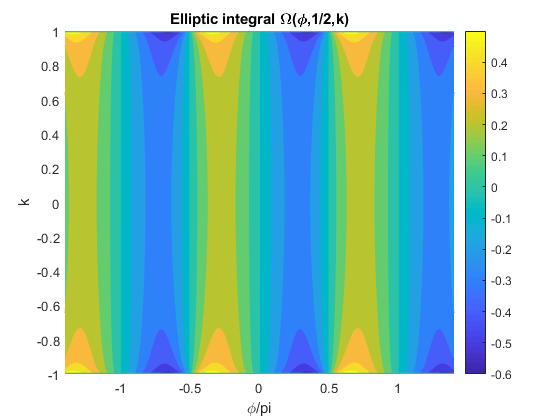

figure
nu = 0.5;
f = @(phi,k)pJacobiOmega(phi*pi,nu,k);
fcontour(f,[-1.4 1.4 -1 1],'Fill','on','LevelList',-0.6:0.1:0.6,'MeshDensity',200)
title('Elliptic integral \Omega(\phi,1/2,k)')
colorbar
xlabel('\phi/pi')
ylabel('k')
grid on

**Example 10**

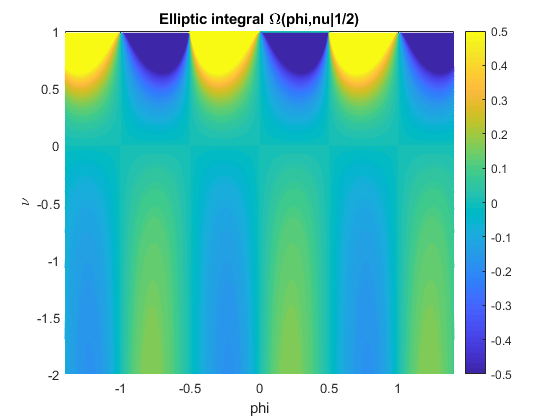

figure
m = 0.5;
f = @(phi,nu)mpJacobiOmega(pi*phi,nu,m);
fcontour(f,[-1.4 1.4 -2 1],'Fill','on','LevelList',-0.5:0.01:0.5,'MeshDensity',200)
title('Elliptic integral \Omega(phi,nu|1/2)')
colorbar
xlabel('phi')
ylabel('\nu')
grid on

**Example 11**

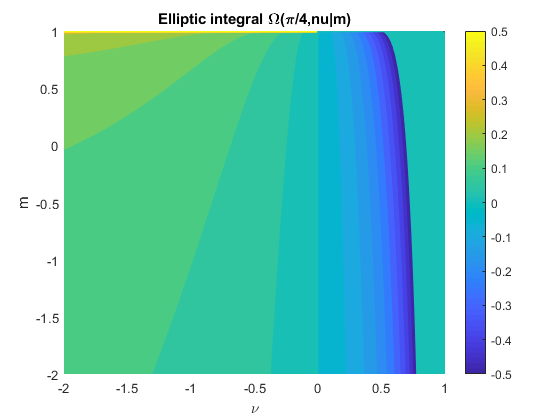

figure
phi = 0.25*pi;
f = @(nu,m)mpJacobiOmega(phi,nu,m);
fcontour(f,[-2 1 -2 1],'Fill','on','LevelList',-0.5:0.05:0.5,'MeshDensity',200)
title('Elliptic integral \Omega(\pi/4,nu|m)')
colorbar
xlabel('\nu')
ylabel('m')
grid on

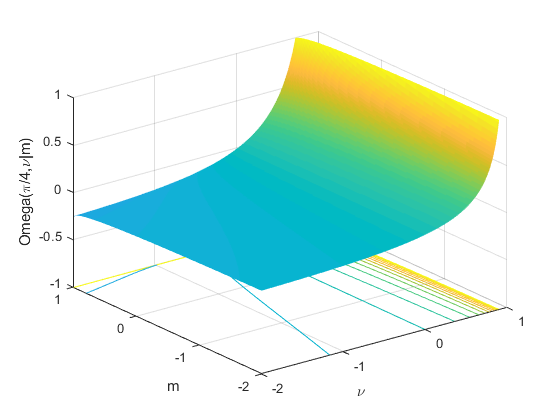

figure
phi=0.25*pi;
nu=-2:0.01:1;
m=-2:0.01:1;
[NU,M]=meshgrid(nu,m);
hs=surfc(NU,M,mpJacobiOmega(pi*phi,NU,M),'EdgeColor','none');
hc = hs(2);
hc.ContourZLevel = -1;
hc.LineWidth = 0.5;
hc.LevelList = -1:0.1:1;
view(3)
caxis([-1 1])
xlabel('\nu')
ylabel('m')
zlabel('Omega(\pi/4,\nu|m)')
zlim([-1 1])
grid on

## More About

[Abramowitz and Stegun. Handbook of Mathematical Functions](http://people.math.sfu.ca/~cbm/aands/frameindex.htm)

[Elliptic Integrals, NIST Digital Library of Mathematical Functions](https://dlmf.nist.gov/19)

[Elliptic integrals, Wikipedia](https://en.wikipedia.org/wiki/Elliptic_integral)

[Higher Transcendental Functions](http://apps.nrbook.com/bateman/Vol2.pdf) 

## **References**

[1] R.G.Langebartel, "Fourier expansions of rational fractions of   elliptic integrals and Jacobian elliptic functions". SIAM  J. Math. Anal. 11, 3, 1980, pp 506-513

[2] D.F. Lawden, Elliptic functions and applications, Springer-Verlag, New York, 1989.

## See Also